# Analyzer_branchCurrents.mlx

## This file statistically analyzes the branch currents for symptoms of Critical Slowing Down.

#### This script changes all interpretation parameters to LaTeX. Plot titles, labels, ticks, etc. will now be shown in the superior LaTeX representation instead of the generic, uninspiring regular MATLAB font.

system_name = 'ieee9'

sampling_rate = 0.0100

T = 3

W = 300

bifurcationIdx = 10724

GKS = function_handle with value:
    @(n,sigma_f)(1/(sqrt(2*pi)*sigma_f))*exp(-n^2/(2*(sigma_f^2)))


convolutionMargin = 53

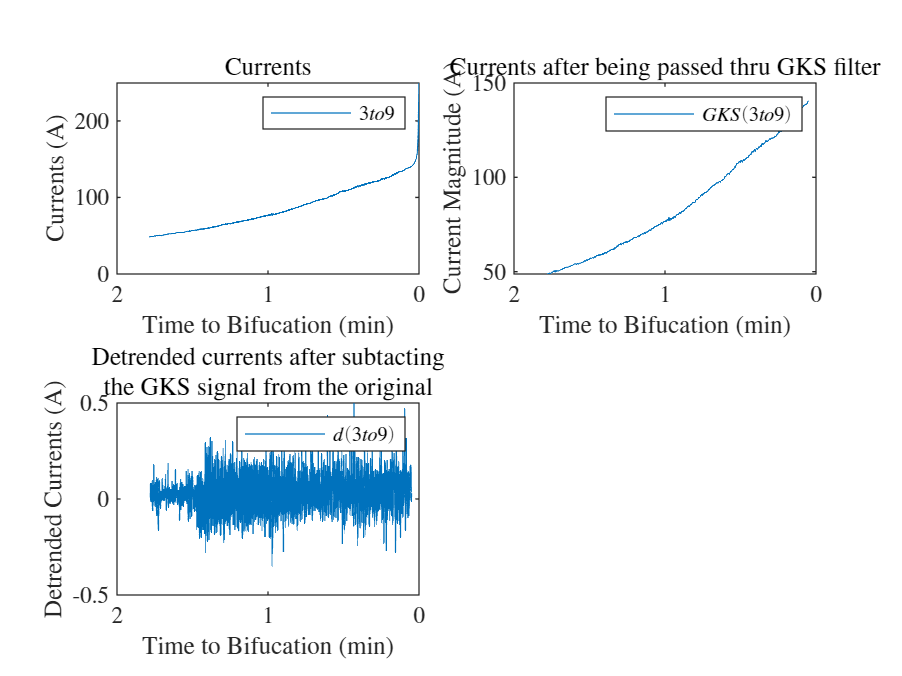

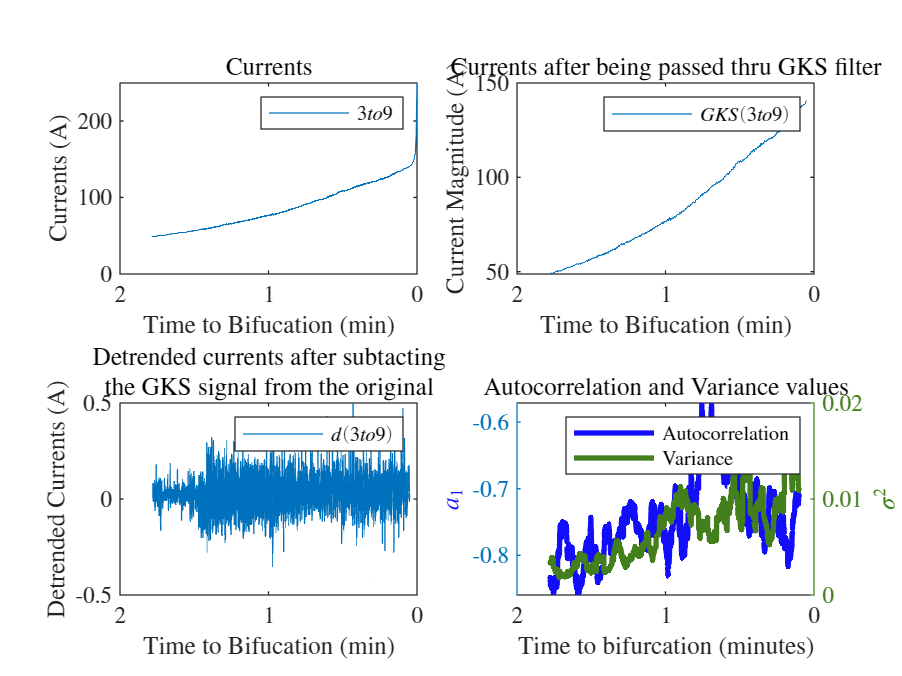

Elapsed time is 129.742805 seconds.


list_factory = fieldnames(get(groot,'factory'));

index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

tic
folder_name = 'saved_outputs/'; %subfolder where data will be stored

system_name = 'ieee9'

tableName = strcat(folder_name, 'nominalValuesTable_',...
    system_name, '.csv');

nominalValuesTable = readtable(tableName);

branchesToPlot = [1 2 3 4 5 6 7 8 9]

sampling_rate = nominalValuesTable.sampling_rate
T = nominalValuesTable.T
W = nominalValuesTable.W

currentsArrName = strcat(folder_name,'currents_', ...
    system_name, '.mat');
currentsArr = load(currentsArrName);
currentsArr = currentsArr.currentsArr;

bifurcationIdx = size(currentsArr, 1)
indicesToPlotTruncated = 1:bifurcationIdx;
xaxisTruncated = (bifurcationIdx - indicesToPlotTruncated)...
    *sampling_rate/(60);

#### Time to smooth the branch currents using Gaussian Kernel Smoothing (GKS).

sigma_f = 5;
GKS = @(n, sigma_f) (1/...
    ( sqrt(2*pi) * sigma_f ))*exp(-n^2/( 2 * (sigma_f^2) ))
% syms GKS_sym(n, sigma_f)
% GKS_sym(n,sigma_f) = (1/( sqrt(2*pi) * sigma_f )) * exp(-n^2/( 2 * (sigma_f^2) ))
% var = vpa(GKS_sym)
gksFilter = [];
for n = 1:W
    gksFilter(n) = GKS(n, sigma_f);
end
gksFilter = gksFilter.*(1/sum(gksFilter));
gks_currentsArr = [];

#### Convolve Bus Voltages with GKS filter for every branch.

for branch = 1:size(currentsArr,2)
    gks_currentsArr(:, branch) = ...
        conv(currentsArr(:, branch), gksFilter, 'full');
end

save(strcat(folder_name, 'gks_currents_', ...
    system_name, '.mat'), 'gks_currentsArr');

convolutionMargin = floor(bifurcationIdx*0.005)
indicesToPlotPostConvolution = 1+convolutionMargin:bifurcationIdx-W+1;
xaxisPostConvolution = (bifurcationIdx - indicesToPlotPostConvolution)...
    *sampling_rate/(60);

currentsDetrendedArr = ...
    currentsArr(indicesToPlotPostConvolution, :) -...
    gks_currentsArr(indicesToPlotPostConvolution, :);

save(strcat(folder_name, 'currentsDetrended_', ...
    system_name, '.mat'), 'currentsDetrendedArr');

#### Calculate Autocorrelations and Variances

ar1_vector = ...
    zeros(length(currentsDetrendedArr)-W, length(branchesToPlot));
var_vector = ...
    zeros(length(currentsDetrendedArr)-W, length(branchesToPlot));

for i = 1:length(branchesToPlot)
    currentBranch = branchesToPlot(i);
    for startingSample = 1:length(currentsDetrendedArr)-W
        sys = ar(currentsDetrendedArr...
            (startingSample:startingSample+W-1, currentBranch), ...
            1, 'ls');
        [num,den] = tfdata(sys,'v');
    %     a1 = abs(den(2));
        a1 = den(2);
        ar1_vector(startingSample, i) = a1;
        sigma_squared = ...
            var(currentsDetrendedArr(...
            startingSample:startingSample+W-1, currentBranch));
        var_vector(startingSample, i) = sigma_squared;
    end
end

save(strcat(folder_name,'ar1_vector_currents_', ...
    system_name, '_', num2str(T), '_sec.mat'), 'ar1_vector');

save(strcat(folder_name,'var_vector_currents_', ...
    system_name, '_', num2str(T), '_sec.mat'), 'var_vector');

toc

